# Experiment 7.1

## Name: Tim Roche

## Objectives

To verify the effect of input waveform, loop gain, and system type upon steady-state errors.

### Minimum Required Software Packages

MATLAB, Simulink, and the Control System Toolbox.

## Prelab

### Problem 1

*What system types will yield zero steady-state error for step inputs?*

**Answer:**

Type 1, Type 2 systems and above will yield zero steady state error for unit step inputs.

### Problem 2

*What system types will yield zero steady-state error for ramp inputs?*

**Answer:**

Type 2 systems and any type above will produce zero steady styate error for ramp inputs. 

### Problem 3

*What system types will yield infinite steady-state error for ramp inputs?*

**Answer:**

Type 0 systems will produce infinite steady state error for ramp inputs.

### Problem 4

*What system types will yield zero steady-state error for parabolic inputs?*

**Answer:**

No system types from 0 to 2 but any system type greater than or equal to type 3 would. 

### Problem 5

*What system types will yield infinite steady-state error for parabolic inputs?*

**Answer:**

Type 0 and Type 1 systems will yield infinite steady state error for parabolic inputs.

### Problem 6

*For the negative feedback system of Figure P6.19 where*$G(s) = \frac{K(s+6)}{(s+4)(s+7)(s+9)(s+12)}$ and $H(s) = 1$, calculate the steady-state error in terms of $K$ for the following inputs: $5u(t)$, $5tu(t)$, and $5t^2u(t)$. 

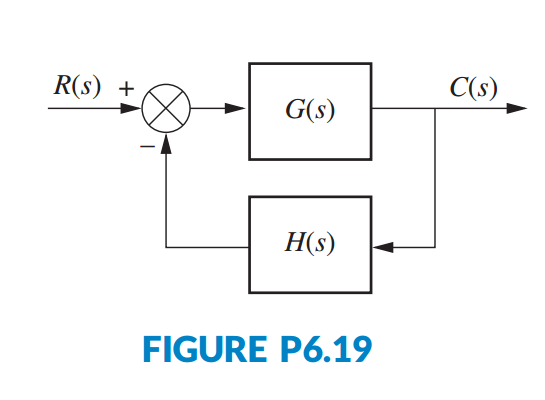

**Answer:**

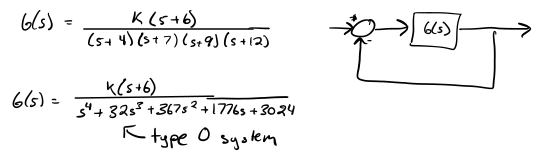

**5u(t)**

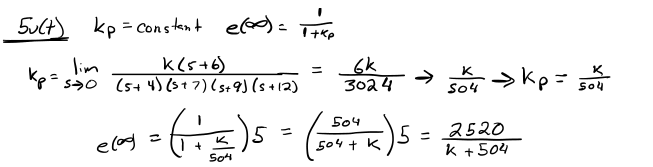

**5tu(t)**

#### 

**5t^2 u(t)**

### Problem 7

*Repeat Prelab 6 for *$G(s) = \frac{K(s+6)(s+8)}{s(s+4)(s+7)(s+9)(s+12)}$ and $H(s) = 1$.

**Answer:**

**5u(t)**

**5tu(t)**

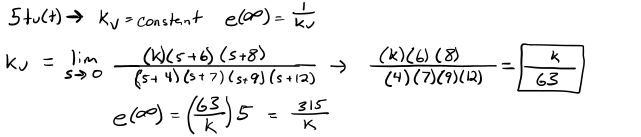

**5t^2u(t)**

### Problem 8

*Repeat Prelab 6 for *$G(s) = \frac{K(s+1)(s+6)(s+8)}{s^2(s+4)(s+7)(s+9)(s+12)}$ and $H(s) = 1$.

**Answer:**

**5u(t)**

**5tu(t)**

**5t^2u(t)**

## Lab

### Problem 1

*Using Simulink, set up the negative feedback system of Prelab 6. Plot on one graph the error signal of the system for an input of *$5u(t)$ and $K$=50, 500, 1000, and 5000. Repeat for inputs of $5tu(t)$ and $5t^2u(t)$

**Step**

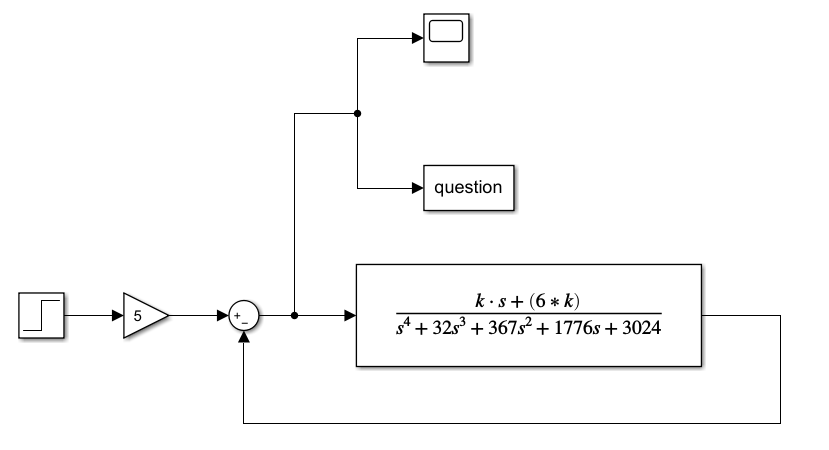

**Ramp**

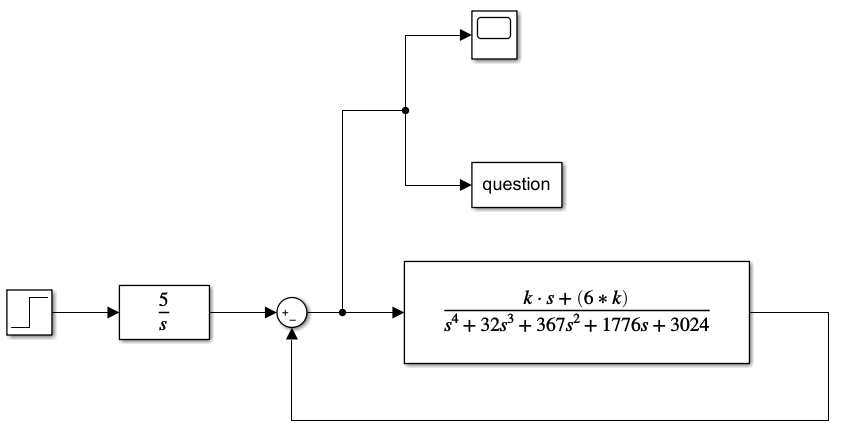

**Para**

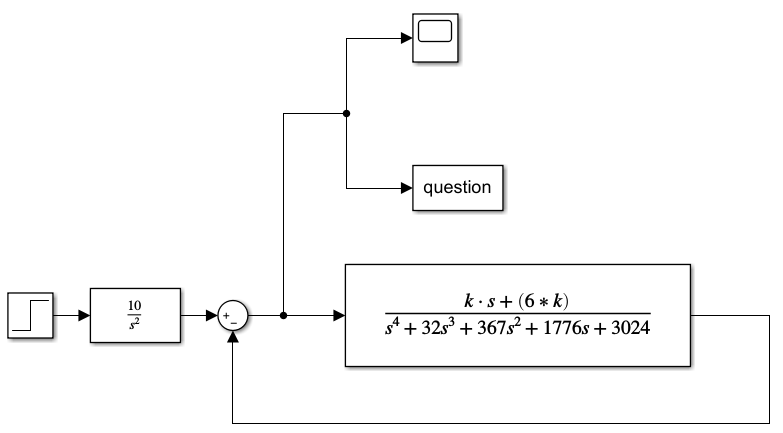

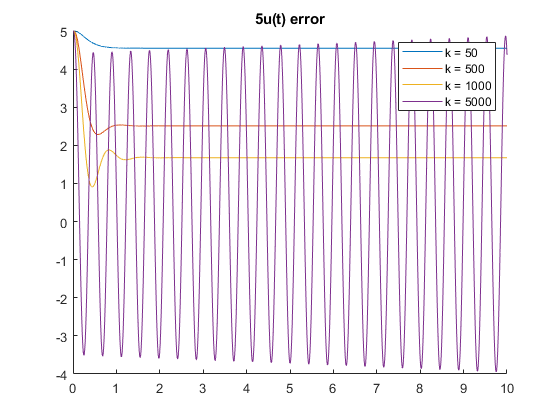

clear all;
close all;
figc = 1;

k_vals = [50 500 1000 5000];
SS_vals = zeros(1, length(k_vals));
figure(figc); figc = figc + 1;
title("5u(t) error");
hold on
for it=1:length(k_vals)
    
    k = k_vals(it);
    
    simOut = sim('ex7_6_step.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
   
    SS_vals(it) = simOut.question.Data(length(simOut.question.Data));
    
end 
hold off
legend("k = "+k_vals);

disp("5u(t) error")

5u(t) error


for SS_ind=1:3
    disp("k = " + k_vals(SS_ind) + " SS = "+ SS_vals(SS_ind))
end

k = 50 SS = 4.5487
k = 500 SS = 2.51
k = 1000 SS = 1.6755


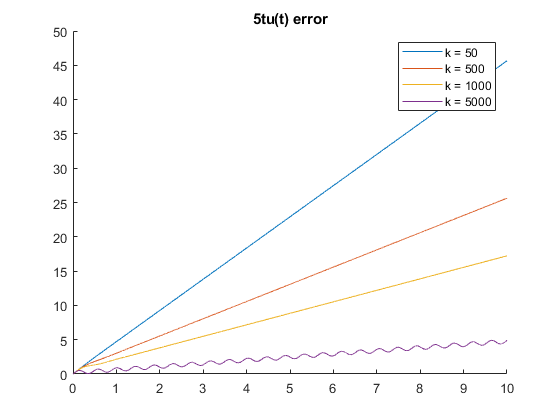


figure(figc); figc = figc + 1;
title("5tu(t) error");
hold on
for it=1:length(k_vals)
    
    k = k_vals(it);
    
    simOut = sim('ex7_6_ramp.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
   
end 
hold off
legend("k = "+k_vals);

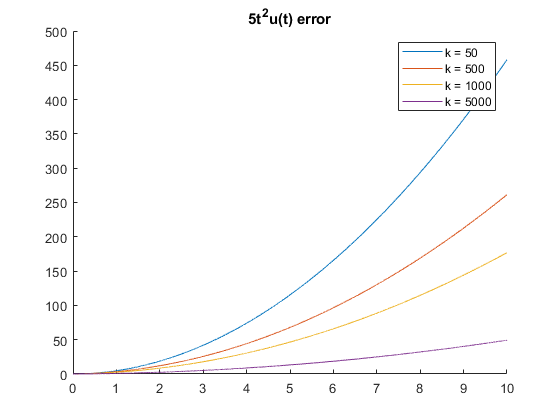


figure(figc); figc = figc + 1;
title("5t^2u(t) error");
hold on
for it=1:length(k_vals)
    
    k = k_vals(it);
    
    simOut = sim('ex7_6_para.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
    
end 
hold off
legend("k = "+k_vals);

### Problem 2

*Using Simulink, set up the negative feedback system of Prelab 7. Plot on one graph the error signal of the system for an input of *$5u(t)$ and $K$=50, 500, 1000, and 5000. Repeat for inputs of $5tu(t)$ and $5t^2u(t)$.

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

**Step**

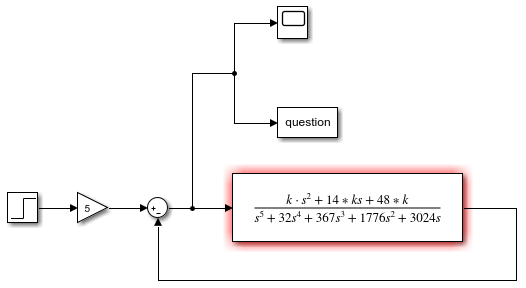

**Ramp**

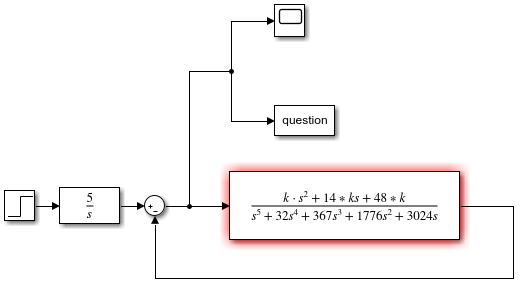

**Para**

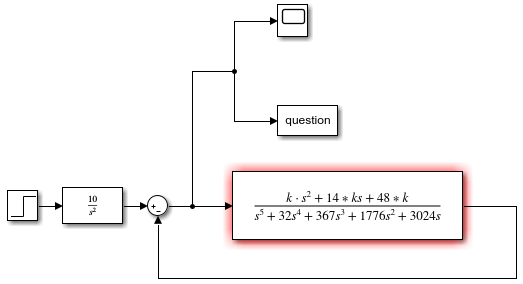

disp("Problem 2")

Problem 2


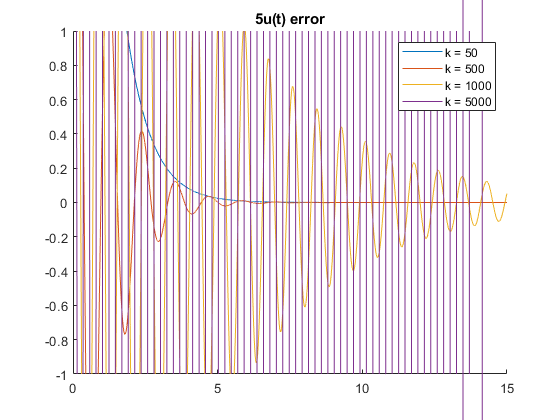

k_vals = [50 500 1000 5000];
SS_vals = zeros(1, length(k_vals));

figure(figc); figc = figc + 1;
title("5u(t) error");
hold on
for it=1:length(k_vals)
    
    k = k_vals(it);
    
    simOut = sim('ex7_7_step.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
   
    SS_vals(it) = simOut.question.Data(length(simOut.question.Data));
end 
hold off
ylim([-1, 1])
legend("k = "+k_vals);

disp("5u(t) error")

5u(t) error


for SS_ind=1:3
    disp("k = " + k_vals(SS_ind) + " SS = "+ SS_vals(SS_ind))
end

k = 50 SS = 1.7439e-07
k = 500 SS = 5.2226e-07
k = 1000 SS = 0.051701


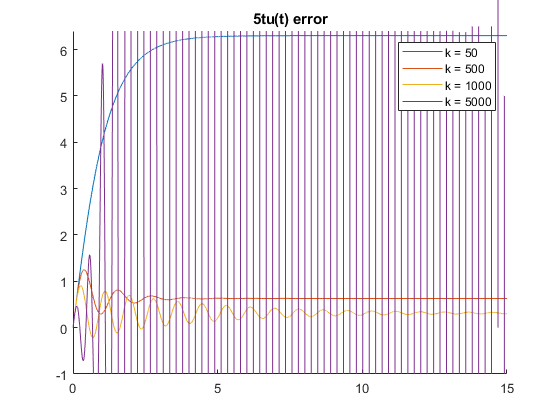


figure(figc); figc = figc + 1;
title("5tu(t) error");
hold on
for it=1:length(k_vals)
    
    k = k_vals(it);
    
    simOut = sim('ex7_7_ramp.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
   
    SS_vals(it) = simOut.question.Data(length(simOut.question.Data));
    
end 
hold off
ylim([-1, 6.4])
legend("k = "+k_vals);

disp("5tu(t) error")

5tu(t) error


for SS_ind=1:3
    disp("k = " + k_vals(SS_ind) + " SS = "+ SS_vals(SS_ind))
end

k = 50 SS = 6.3
k = 500 SS = 0.63
k = 1000 SS = 0.30301


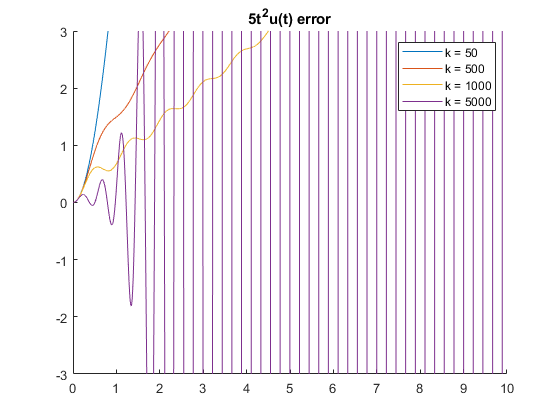


figure(figc); figc = figc + 1;
hold on
for it=1:length(k_vals)
    
    k = k_vals(it);
    
    simOut = sim('ex7_7_para.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
   
    SS_vals(it) = simOut.question.Data(length(simOut.question.Data));    
end 
hold off
title("5t^2u(t) error");
ylim([-3, 3])
legend("k = "+k_vals);  

### Problem 3

*Using Simulink, set up the negative feedback system of Prelab 8. Plot on one graph the error signal of the system for an input of *$5u(t)$ and $K$= 200, 400, 800, and 1000. Repeat for inputs of $5tu(t)$ and $5t^2u(t)$.

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

**Step**

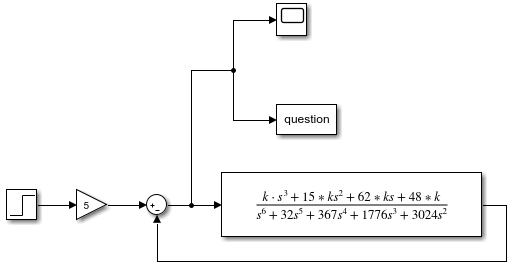

**Ramp**

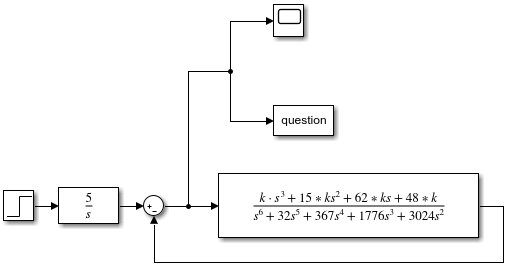

**Para**

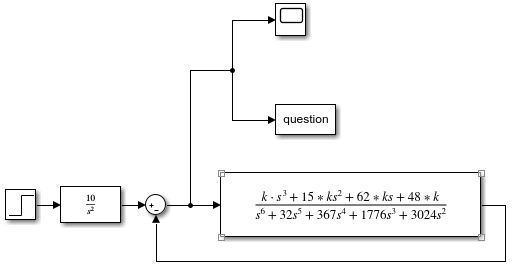

disp("Problem 3");

Problem 3


k_vals = [200 400 800 1000];
SS_vals = zeros(1, length(k_vals));

figure(figc); figc = figc + 1;
title("5u(t) error");
hold on
for it=1:length(k_vals)
    
    k = k_vals(it);
    
    simOut = sim('ex7_8_step.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
   
    SS_vals(it) = simOut.question.Data(length(simOut.question.Data));
end 
hold off

legend("k = "+k_vals);
disp("5tu(t) error")

5tu(t) error


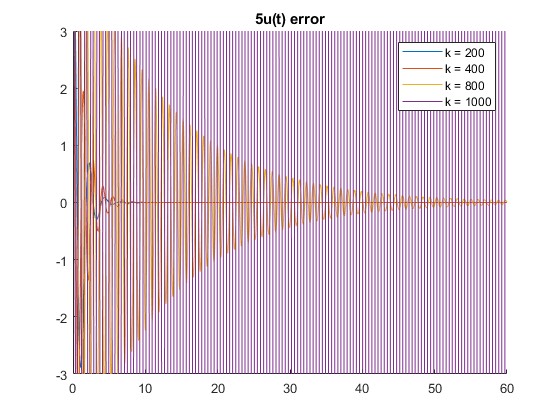

ylim([-3 3])

for SS_ind=1:3
    disp("k = " + k_vals(SS_ind) + " SS = "+ SS_vals(SS_ind))
end

k = 200 SS = 0
k = 400 SS = 0
k = 800 SS = 0.0039953


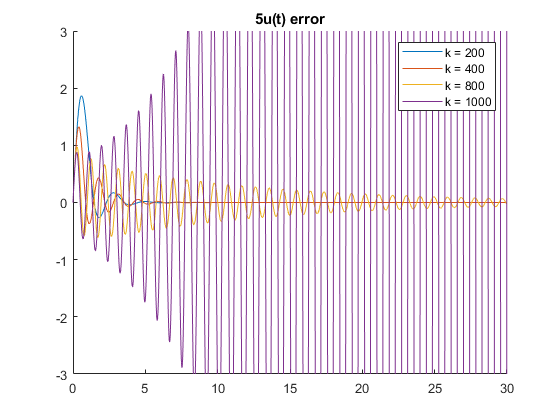


figure(figc); figc = figc + 1;
title("5u(t) error");
hold on
for it=1:length(k_vals)
    
    k = k_vals(it);
    
    simOut = sim('ex7_8_ramp.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
   
    SS_vals(it) = simOut.question.Data(length(simOut.question.Data));
end 
hold off
ylim([-3 3])
legend("k = "+k_vals);

disp("5u(t) error")

5u(t) error


for SS_ind=1:3
    disp("k = " + k_vals(SS_ind) + " SS = "+ SS_vals(SS_ind))
end

k = 200 SS = -1.5348e-12
k = 400 SS = 4.5929e-11
k = 800 SS = -0.034333


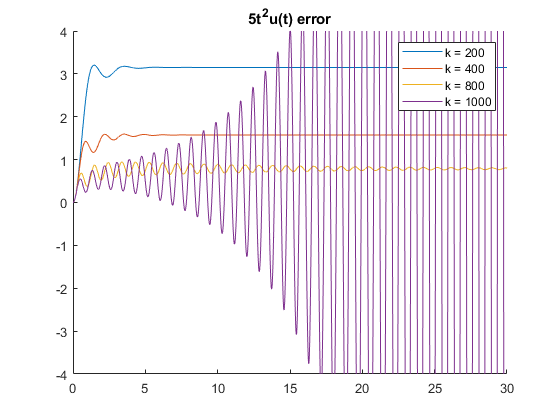


figure(figc); figc = figc + 1;
title("5t^2u(t) error");
hold on
for it=1:length(k_vals)
    
    k = k_vals(it);
    
    simOut = sim('ex7_8_para.slx','ReturnWorkspaceOutputs','on');
    plot(simOut.question.Time, simOut.question.Data);
   
    SS_vals(it) = simOut.question.Data(length(simOut.question.Data));
end 
hold off
ylim([-4 4])
legend("k = "+k_vals);


disp("5u(t) error")

5u(t) error


for SS_ind=1:3
    disp("k = " + k_vals(SS_ind) + " SS = "+ SS_vals(SS_ind))
end

k = 200 SS = 3.15
k = 400 SS = 1.575
k = 800 SS = 0.80498


## Postlab

### Problem 1

*Use your plots from Lab 1 and compare the expected steady-state errors to those calculated in the Prelab. Explain the reasons for any discrepancies.*

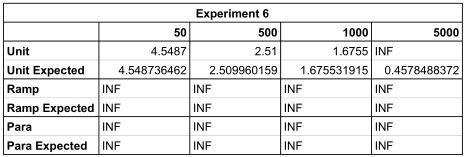

For gains between 50 and 1000, the expected value and the simulated value perfectly match. As for the gain of 5000, this difference is due to the fact that a gain of 5000 makes the system unstable as it pushes the poles into the right hand plane. This is because in the transfer function for the feedback system, gain k is in the denominator, affecting the locations of the poles. These steady state error calculations assume that the system will arive at a steady state assuming the system type facilitates it. So for already unstable systems, if put through the steady state error caclulations, the calculations will output a value but this value will have no basis in reality since they are unstable. 

### Problem 2

*Use your plots from Lab 2 and compare the expected steady-state errors to those calculated in the Prelab. Explain the reasons for any discrepancies.*

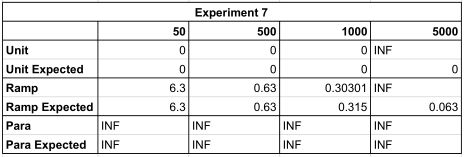

For gains between 50 and 500, there is no difference between the calculated and the simulated result. However, the gain of 1000 has a very minor differance with the theoretical value. This small difference could be justified as due to the systems not perfectly being at steady state at the last data point of the response. If the simulation was extended indefinitely, this value would converge to the calculated value. Simular to the previous problem, a gain of 5000 renders the system unstable, but these steady state calculations assume stability, so if the poles are pushed into the right hand plane due to the gain, these calculations are rendered useless. 

### Problem 3

*Use your plots from Lab 3 and compare the expected steady-state errors to those calculated in the Prelab. Explain the reasons for any discrepancies.*

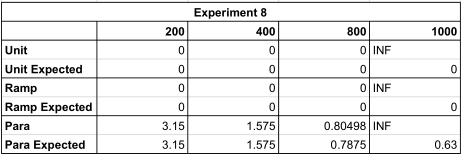

For all inputs for gains between 200 and 400, the predicted value perfectly matches the experimental value. However, for a gain of 800, the parabolic input value differs by 0.02 from the calulated value. This is due to the fact that the system was still slightly occilating when the simulation ended, leading to a slightly incorrect value. However, such a difference is insigifigant. The large gain of 1000 manages to push this particular system's poles into the right hand plane, leading to unstibility. Such unstability is not accounted for by the steady state error equations. This is the reasoning for this discrepancy*.* 